# CÁLCULO NUMÉRICO

# PRÁCTICA 4 · TEMA 5 · INTERPOLACIÓN Y AJUSTE

GRUPO:  **GRUPO 4 **

NOMBRES: 

**JUAN CANO **

**DAVID MARÍN **

**PABLO MENDIETA **

**DAVID MORENO**

FECHA: **18 / 02 / 24**

## P04_T05_P01. Regresión lineal

### Respuesta

**a)** Función Adjuntada:  `[a, Er] = RegresionLineal(x,y)`

**b)**

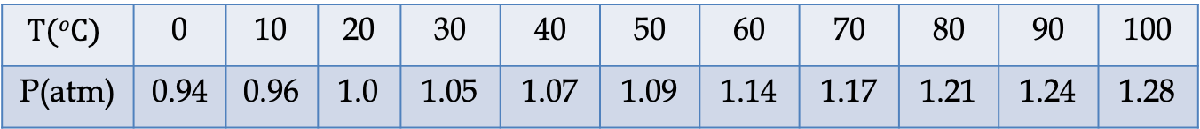

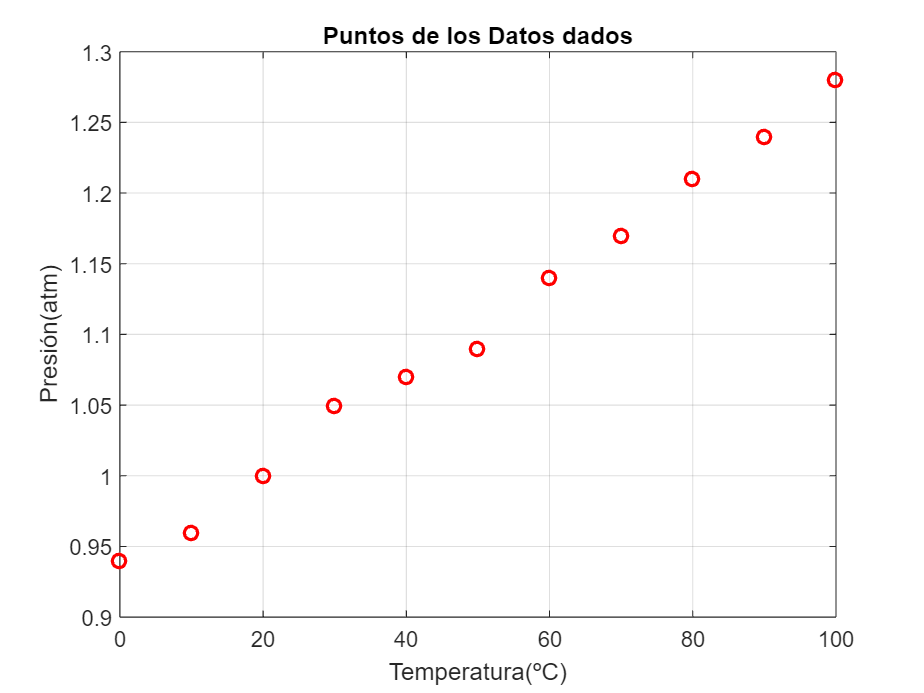

clc, clear, clf
T = 0 : 10 : 100;
P = [0.94 0.96 1.0 1.05 1.07 1.09 1.14 1.17 1.21 1.24 1.28]; 

% Gráfica 
plot(T,P,'or', 'LineWidth',1.5)
title('Puntos de los Datos dados')
xlabel('Temperatura(ºC)')
ylabel('Presión(atm)')
grid on
hold off

Cálculo de la recta de regresión lineal:

clf
[a, Er ] = RegresionLineal(T, P);
fprintf('Recta de regresion lineal: P = %.4f·T + %.4f', a(1), a(2));

Recta de regresion lineal: P = 0.0034·T + 0.9336

fprintf('Error estandar de la recta de regresión: %.4f', Er)

Error estandar de la recta de regresión: 0.0078

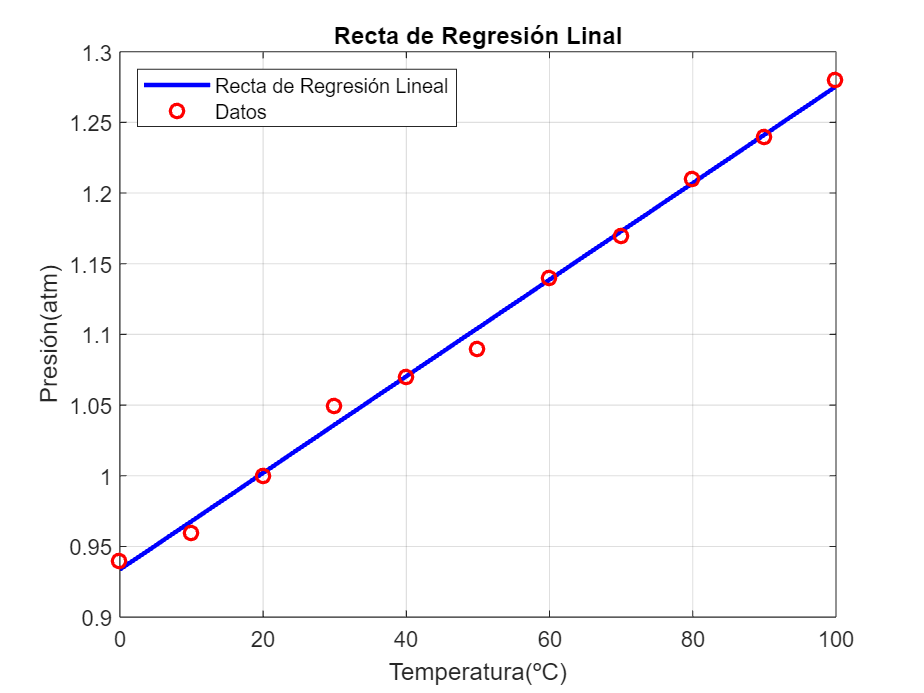


% Gráfica
xp = linspace(min(T) ,max(T),100);
yp = a(1)*xp + a(2);
plot(xp,yp,'b','LineWidth',2)
hold on
plot(T,P,'or', 'LineWidth',1.5)
title('Recta de Regresión Linal')
xlabel('Temperatura(ºC)')
ylabel('Presión(atm)')
legend('Recta de Regresión Lineal', 'Datos', 'Location', 'northwest')
grid on
hold off

Para hallar $T_0$(cero absoluto)  de foma analítica igualamos $P$ a 0:


$$0=a_0 \cdot T_0 +a_1 \;\to T_0 =\frac{a_1 }{{-a}_0 }$$


Sabemos que la temperatura mínima está en torno a $-273\ldotp 15\;\textrm{ºC}\;\approx 0\;\textrm{ºK}\;$

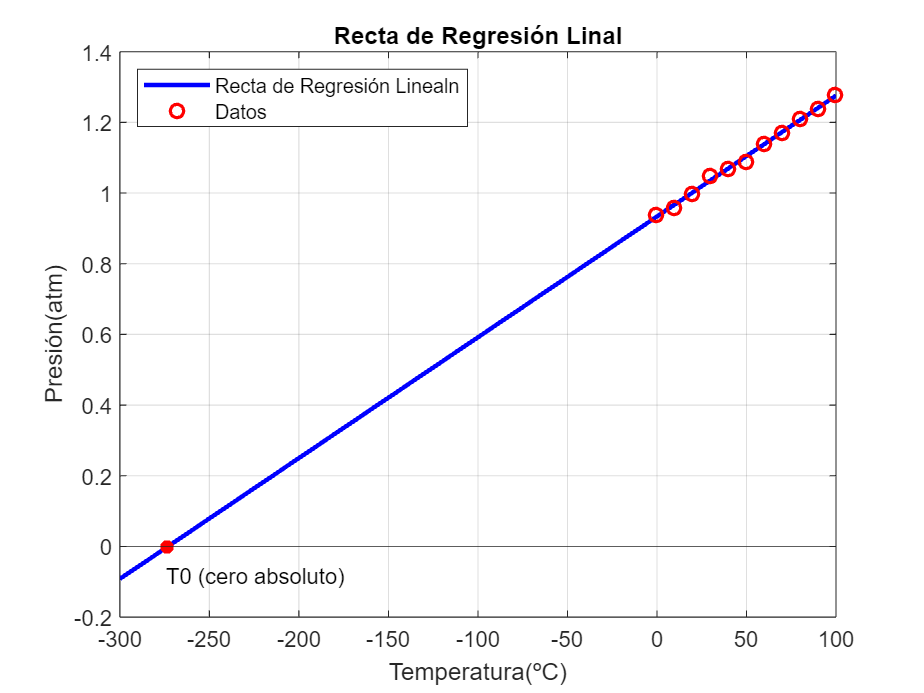

clf
Tcero = -a(2) / a(1);

xp = linspace(-300 ,max(T),100);
yp = a(1)*xp + a(2);

% Gráfica 
plot(xp,yp,'b','LineWidth',2)
hold on
plot(T,P,'or', 'LineWidth',1.5)
title('Recta de Regresión Linal')
xlabel('Temperatura(ºC)')
ylabel('Presión(atm)')
yline(0)
x_punto = Tcero ;
y_punto = 0;
plot(x_punto, y_punto, '*r', 'LineWidth', 2.5);
text(Tcero - 1, -0.08, 'T0 (cero absoluto)', 'FontSize', 10 );
legend('Recta de Regresión Linealn', 'Datos', 'Location', 'northwest')
grid on
hold off

fprintf(' El valor de T0 (cero absoluto) es: %.4f ºC', Tcero)

 El valor de T0 (cero absoluto) es: -273.1383 ºC

## P04_T05_P01. AJUSTE POLINÓMICO

### Respuesta

**a) **Función Adjuntada: `[p,Er] = PoliMulti(x,y,m)`

**b)**

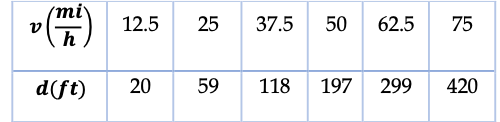

clc, clear, clf
v = 12.5 : 12.5 : 75;
d = [20 59 118 197 299 420];

m = 2; % segundo grado 

[p,Er] = PoliMulti(v,d,m);


fprintf('Polinomio de Interpolación: d = %.4f·v^2 + %.4f·v + %.4f', p(1), p(2), p(3))

Polinomio de Interpolación: d = 0.0665·v^2 + 0.5777·v + 2.6000

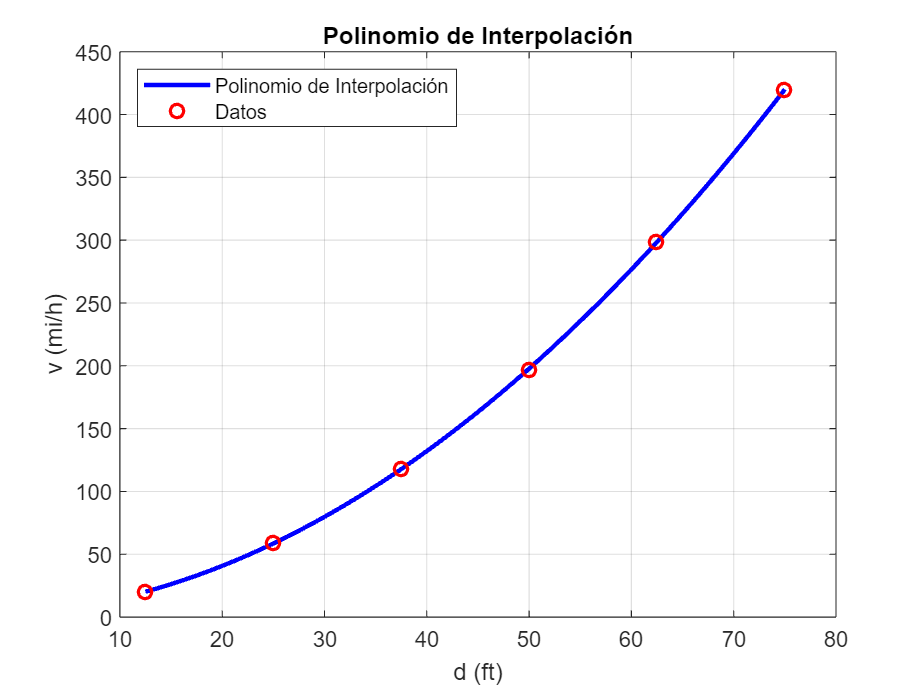


xp = linspace(min(v) ,max(v),100);
yp = p(1)*xp.^2 + p(2)*xp + p(3);

% gráfica
plot(xp,yp,'b','LineWidth',2)
hold on
plot(v,d,'or', 'LineWidth',1.5)
title('Polinomio de Interpolación')
xlabel('d (ft)')
ylabel('v (mi/h)')
legend('Polinomio de Interpolación', 'Datos', 'Location', 'northwest')
grid on
hold off


fprintf('Error Total: %.4f', Er)

Error Total: 1.0571

## P04_T05_P03. Interpolación mediante polinomios de Lagrange

### Respuesta

**a) ** Función Adjuntada:  `Yint = LagINT(x,y,Xint)` 

**b)**

 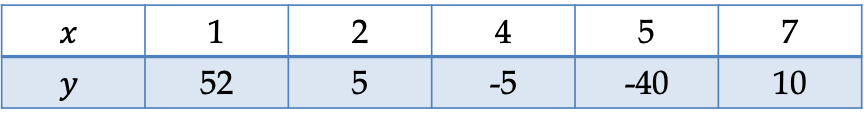

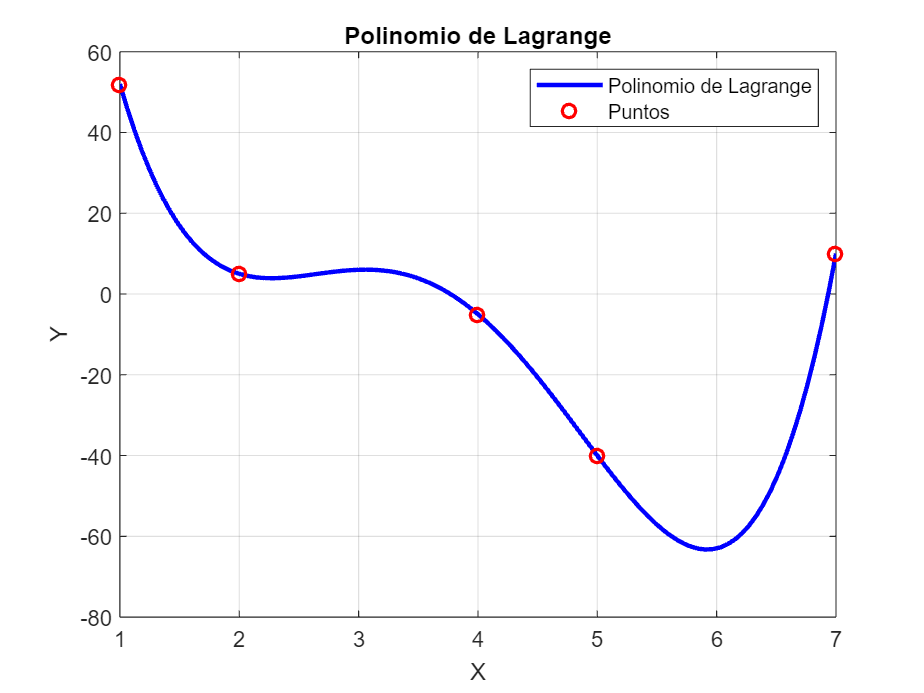

clc, clear, clf

x = [1 2 4 5 7 ];
y = [52 5 -5 -40 10];

xp = linspace( x(1), x(length(x)), 100 );
yp= zeros(1,100);

% Cáclulo de los valores interpolados de y 
for i = 1:100
    yp(i) = LagINT(x,y,xp(i));
end   

% Gráfica 
plot(xp,yp,'b','LineWidth',2)
hold on
plot(x, y, 'or', 'LineWidth',1.5)
title('Polinomio de Lagrange')
legend('Polinomio de Lagrange','Puntos')
grid on 
xlabel('X')
ylabel('Y')
hold off 

Cálculo del valor interpolado para $x=3$

Yint3 = LagINT(x,y,3);
fprintf('Valor interpolado para x = 3: y = %.4f',Yint3)

Valor interpolado para x = 3: y = 6.0000

## P04_T05_P04. Interpolación mediante polinomios de Newton

### Respuesta

**a) **Función Adjuntada: `Yint = NewtonINT(x,y,Xint) `

**b)**

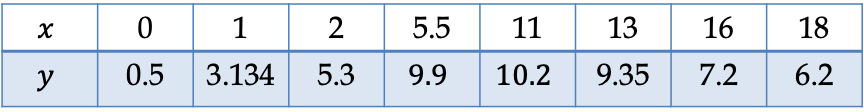

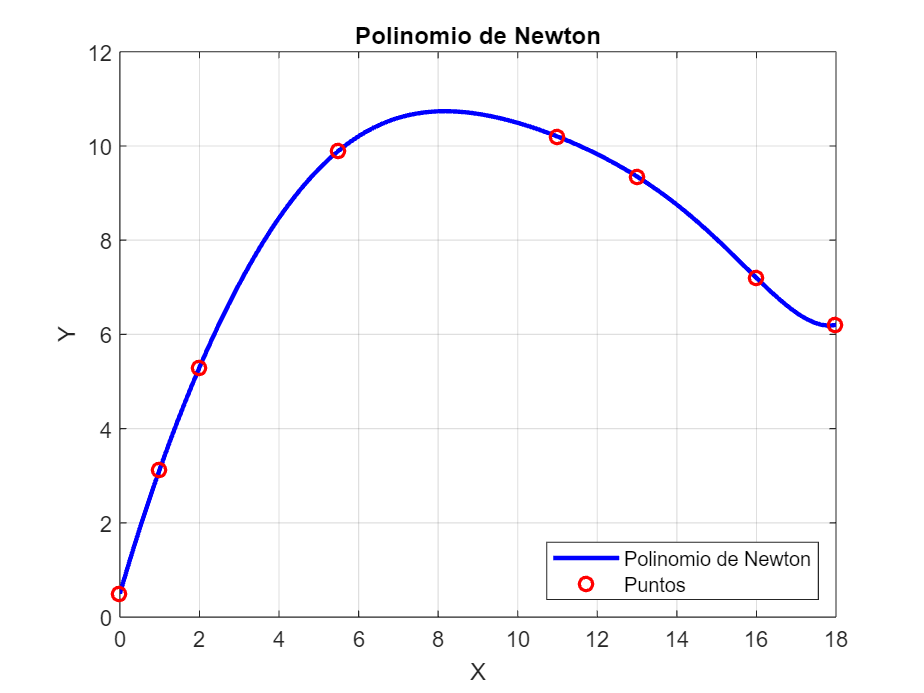

clc, clear, clf

x = [ 0 1 2 5.5 11 13 16 18];
y = [0.5 3.134 5.3 9.9 10.2 9.35 7.2 6.2];
Xint = 8;

Yint = NewtonINT(x,y,Xint);

xp = linspace( x(1), x(length(x)), 100 );
yp= zeros(1,100);

% Cáclulo de los valores interpolados de y 
for i = 1:100
    yp(i) =  NewtonINT(x,y,xp(i));
end   

plot(xp,yp,'b','LineWidth',2)
hold on
plot(x, y, 'or', 'LineWidth',1.5)
title('Polinomio de Newton')
legend('Polinomio de Newton','Puntos','Location', 'southeast')
grid on 
xlabel('X')
ylabel('Y')
hold off 

Cálculo del valor interpolado para $x=8$

Yint8 = NewtonINT(x,y,8); 
fprintf('Valor interpolado para x = 8: y = %.4f',Yint)

Valor interpolado para x = 8: y = 10.7345

## P04_T05_P05. Interpolación mediante spline cúbicas

###  Respuesta

**a) **Función adjuntada: `Yint = SplineCub(x,y,xint)`

**b)**

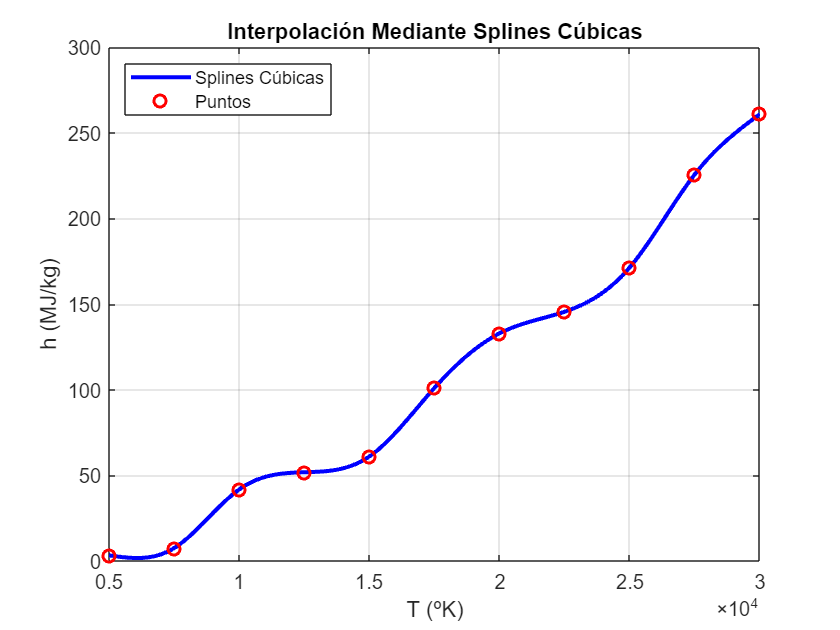

clc, clear, clf

T = [5 7.5 10 12.5 15 17.5 20 22.5 25 27.5 30];
T = T * 10^3;
h = [3.3 7.5 41.8 51.8 61 101.1 132.9 145.5 171.4 225.8 260.9];

% Cáclulo de los valores interpolados de y 
xp = linspace( T(1), T(length(T) ), 100);
yp= zeros(1,100);
for i = 1:100
    yp(i) =  SplineCub(T,h,xp(i));
end   

% Gráfica 
plot(xp,yp,'b','LineWidth',2)
hold on
plot(T, h, 'or', 'LineWidth',1.5)
title('Interpolación Mediante Splines Cúbicas')
legend('Splines Cúbicas','Puntos','Location', 'northwest')
grid on 
xlabel('T (ºK)')
ylabel('h (MJ/kg)')
hold off 

Calculamos la entalpía por unidad de masa a $T_1 =14000\textrm{ºK}$  y $T_2 =24000\textrm{ºK}$

clf
T1 = 14000;
Y1 = SplineCub(T,h,T1)

Y1 = 54.1160

T

T =         5000        7500       10000       12500       15000       17500       20000       22500       25000       27500       30000


h

h =     3.3000    7.5000   41.8000   51.8000   61.0000  101.1000  132.9000  145.5000  171.4000  225.8000  260.9000


fprintf('El valor de la entalpía por unidad de masa para la temperatura %d ºK, es: %.4f MJ/kg ', T1, Y1)

El valor de la entalpía por unidad de masa para la temperatura 14000 ºK, es: 54.1160 MJ/kg 


T2 = 24000;
Y2 = SplineCub(T,h,T2);
fprintf('El valor de la entalpía por unidad de masa para la temperatura %d ºK, es: %.4f MJ/kg ', T2, Y2)

El valor de la entalpía por unidad de masa para la temperatura 24000 ºK, es: 157.0608 MJ/kg 

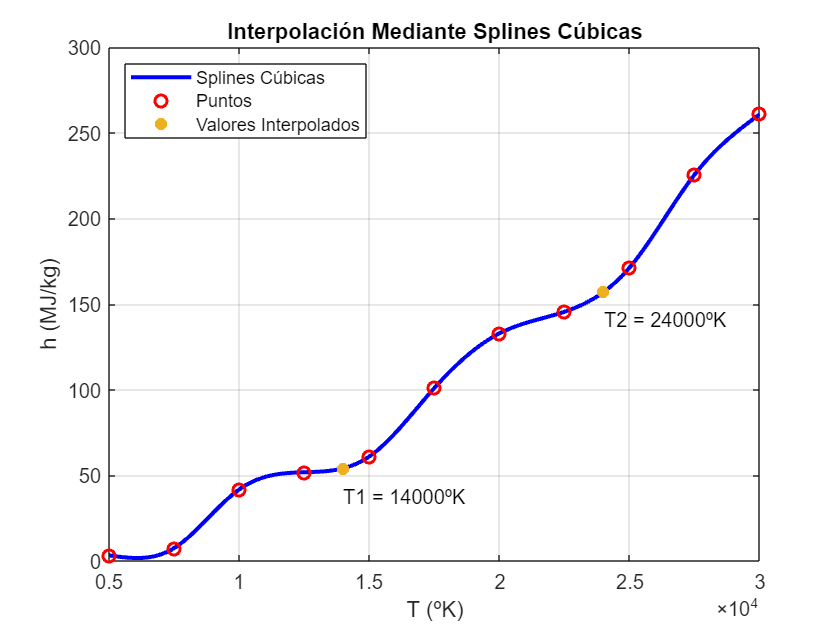


% Gráfica 
plot(xp,yp,'b','LineWidth',2)
hold on
plot(T, h, 'or', 'LineWidth',1.5)
x_punto = [T1, T2];
y_punto = [Y1,Y2];
plot(x_punto, y_punto, '*', 'LineWidth', 2.5)
text(x_punto(1) - 1, y_punto(1) - 16, 'T1 = 14000ºK', 'FontSize', 10 )
text(x_punto(2) - 1, y_punto(2) - 16, 'T2 = 24000ºK', 'FontSize', 10 )
grid on 
title('Interpolación Mediante Splines Cúbicas')
legend('Splines Cúbicas','Puntos','Valores Interpolados','Location', 'northwest')
xlabel('T (ºK)')
ylabel('h (MJ/kg)')
hold off 